# Matlab mobile fitness tracker hackathlon

## Team members:

Programmer Athlete - Nikolaos Konstantinou

Marketing Athlete - Giannis Prokopiou

## Small desciption:

In this project, our goal is to make a fitness tracking program using MATLAB®. The matrics tracked are the time of the walking/working out, the distance traveled, steps taken (using two methods) and finally the estimated calories burned.

## Data collection:

The data was collected during the hackathlon event, by walking around NTUA's central square, while recording acceleration and position data from our phoes, using the MATLAB® Mobile™ application.

## Source code:

Note: The file 'timeElapsed.m' must be included on the execution path for the program to run properly.

The user needs to save the device's collected data on the working path in a file named **sensorlog.mat**.

At the begining of the program, some variables need to be defined, such as the user's weight and height, so that calories burned will be calculated correctly.

% Enviroment constants
gravitational_constant_noise = 9.871;

% How to calculate steps
calculate_steps_with = 0;

% Human Constants
human_height = double(1.73); % in meters
human_weight = double(72.5); % in kilograms

% Sensor file to open and read
load sensorlog.mat

% Detection parameters
noise_defiltering_freq = 15; % in Hz
scan_window_size = 11;

sensitivity_threshhold = 0.6;
earth_circumference = 40075017; % in meters

It is important to calculate the **gravitational_constant_noise**, so that the acceleration data are being processed correctly. This is a device specific constant, but is also affected by the gravity, which slighltly chanhes along with the height from the sea.

To calculate this constant, the user needs to lay rest their phone for a while and collect **blank** data. After that, they will need to select a start and end of a time period where the graph is as constant as possible, using the below code:

calc_constant_noise = false;
calc_noise_start_t = double("90");
calc_noise_end_t = double("110");

% Using the user's defined value ranges, calculate the constant using the
% least squares method. The constant is the b in y=ax+b
if calc_constant_noise
    xs = accel_elap_time(calc_noise_start_t < accel_elap_time & accel_elap_time < calc_noise_end_t);
    ys = accelerations(calc_noise_start_t < accel_elap_time & accel_elap_time < calc_noise_end_t);
    n = length(xs);
    m = (n*sum(xs.*ys)-sum(ys)*sum(xs))/(n*sum(xs.^2)-(sum(xs)^2));
    b = (sum(ys)-m*sum(xs))/n;
    fprintf("Relative noise/gravity constant is: %.3f m/s^2\n", b);
end

Note: it is important to check the *calc_constant_noise* checkbox for the calculation to take place.

After the calibration is over, we continue to the data processing:

% Read acceleration data
accelerations = sqrt(Acceleration.X .^2 + Acceleration.Y .^2 + Acceleration.Z .^2);
% Deduct the constant noise that is mostly caused by the gravity
% each phone/sensor has different noise constant so the variable
% must be calibrated for each device
accelerations = accelerations - gravitational_constant_noise;

accel_elap_time = timeElapsed(Acceleration.Timestamp);
% Filter out noise from the data collected
accelerations = lowpass(accelerations, 1/noise_defiltering_freq);

Here we filter the acceleration out of most low noise.

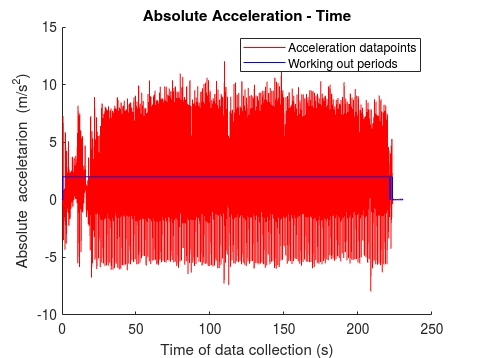

% Calculate the varience of acceleration
accelVariariance = stdfilt(accelerations, true(scan_window_size, 1));
% Figure out at what timestamps the person was working out
workingIndicies = accelVariariance > sensitivity_threshhold;

% Filter out small intervals where momentarely the workingout/idling state
% was switched. This is caused by noise
lastValSeen = workingIndicies(1);
seensize = 0;
for i = 1:size(workingIndicies)
    if workingIndicies(i) == lastValSeen
        seensize = seensize + 1;
    else
        if seensize < 2*scan_window_size
            for j = i-seensize-1:i-1
                workingIndicies(j) = workingIndicies(i); %invert
            end
        end
        seensize = 0;
        lastvalSeen = workingIndicies(i);
    end
end

% Plot acceleration and working out filter line
hold on;
plot(accel_elap_time, accelerations, 'r-');
plot(accel_elap_time, workingIndicies*2, 'b-');
title("Absolute Acceleration - Time");
xlabel("Time of data collection (s)");
ylabel("Absolute acceletarion (m/s^2)");earth_circumference = 40075017;
legend("Acceleration datapoints", "Working out periods");

Here, we filter out small intervals where the state of working our vs idling switches for a small amount of time because of noise. After that, we display the graph of acceleration and whether or not the user is working out.

% Figure out the time periods where the person was working out, after the
% filtering has happened
working_time_intervals = [];
currently_working = workingIndicies(i);
curr_interval_start_at = 0;

for i = 1:size(workingIndicies)
    if currently_working == 1 && workingIndicies(i) == 0
        currently_working = 0;
        working_time_intervals(end+1,1) = curr_interval_start_at;
        working_time_intervals(end,2) = accel_elap_time(i);        
    elseif currently_working == 0 && workingIndicies(i) == 1
        currently_working = 1;
        curr_interval_start_at = accel_elap_time(i);
    end
end

% Calculate and display the total working out time
total_time_worked = sum(working_time_intervals(:, 2) - working_time_intervals(:,1));
fprintf("Worked out for %.2f seconds (%.2f minutes)!", total_time_worked, total_time_worked/60);

Worked out for 222.33 seconds (3.71 minutes)!

In the above code, we calculate the total amount of time and the time intervals when the user worked out. The, we print the total work out time

% Calculate the total distance the person walked/run.
position_lat = Position.latitude;
position_lon = Position.longitude;
posit_elap_time = timeElapsed(Position.Timestamp);

total_distance = 0;
for i = 1:(length(position_lat)-1)
    lat1 = position_lat(i);
    lat2 = position_lat(i+1);
    lon1 = position_lon(i);
    lon2 = position_lon(i+1);   

    degDis = distance(lat1, lon1, lat2, lon2);

    dist = (degDis/360)*earth_circumference;
    total_distance = total_distance + dist;
end

Here, we calculate the total distance walked by the user, using the gps signal data.


% Calculate the total steps taken, basted on the user's preferred method
steps_taken = 0;
steps_text = "";
if calculate_steps_with == 0
    stride = 0.415*human_height;
    steps_taken = round(total_distance/stride);
    steps_text = "(with gps)";
else
    steps_taken = sum(islocalmax(accelerations(workingIndicies)));
    steps_text = "(with acceleration)";
end

% Display the total distance walked and how many steps were taken
fprintf("Walked %.2f meters and took %d steps in total %s\n", total_distance, steps_taken, steps_text);

Walked 297.56 meters and took 414 steps in total (with gps)


 In the above code, we calculate how many steps the user has made. There are 2 main ways of doing that, using the GPS or the accelerometer. Thus, the users selects in the start of the code in what mode to calculate the steps. Of course there is a small difference between these two methods, but both are accurate and reliable enough.

% Calculate the total calories burnt in the workout
MET = 3.5 + (0.1 * total_distance/total_time_worked )/human_height^1.5;
calories_per_min = MET * 0.0175 * human_weight;
cals = calories_per_min * total_time_worked/60;
fprintf("Burnt %.2f calories in total (%.2f cal/min)!\n", cals, calories_per_min);

Burnt 16.73 calories in total (4.52 cal/min)!


Finally, we calculate the total calories burned during the workout using the MET (metabolic equivalent of task) of the user and we print it to the screen.

## Sources:

- [`https://www.ncbi.nlm.nih.gov/pmc/articles/PMC6263649/`](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC6263649/)

- [`https://www.scientificamerican.com/article/bring-science-home-estimating-height-wal`](https://www.scientificamerican.com/article/bring-science-home-estimating-height-wal)

- "Context Impact in Accelometer-Based Walk Detection and Step Counting"  

- ChatGPT questions related to calories calculation. 